# **lmeEEG: Tutorial**

**For details see: **[**https://doi.org/10.1016/j.jneumeth.2023.109991**](https://doi.org/10.1016/j.jneumeth.2023.109991) 

#### Download input files:

- *sEEG_all*: Event-related EEG dataset simulated using the MATLAB-based toolbox SEREEGA (https://github.com/lrkrol/SEREEGA).  Simulated EEG data included a P1-N2-P3 complex with different intercepts for subjects (N = 30) and items (N = 10). Moreover, the P3 was differently modulated according to two experimental conditions (i.e., a two-level experimental factor: A vs. B). 

- *chanlocs*: channel location variable (EEGLAB format)

- *sEEG_table*: Event table specifying Subject (ID), Item, and experimental condition

websave('sEEG_all.mat','https://osf.io/download/5wqmy/'); load('sEEG_all.mat');
websave('sEEG_table.mat', 'https://osf.io/download/ufpgr/'); load('sEEG_table.mat');
addpath(['functions']);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 24 workers.


### STEP 1

#### **Conduct mixed models on each channel/timepoint combination.**

ID = nominal(sEEG_table.ID); Item=nominal(sEEG_table.Item); CON = categorical(sEEG_table.Condition);
mEEG = nan(size(sEEG_all));
for ch = 1:size(sEEG_all,1)
    parfor tpoint = 1:size(sEEG_all,2)
        EEG = double(squeeze(sEEG_all(ch,tpoint,:)));
        EEG = table(EEG,CON,ID,Item);
        m = fitlme(EEG,'EEG~CON+(1|ID)+(1|Item)');
        mEEG(ch,tpoint,:) = fitted(m,'Conditional',0)+residuals(m); % Extract marginal EEG
    end
end

% Extract design matrix X
EEG = double(squeeze(sEEG_all(1,1,:)));
EEG = table(EEG,CON,ID,Item);
m = fitlme(EEG,'EEG~CON+(1|ID)+(1|Item)');
X = designMatrix(m);

clear EEG

### **STEP 2 **

#### **Perform mass univariate linear regressions on “marginal” EEG data.**

t_obs = nan(size(mEEG,1),size(mEEG,2),size(X,2));
betas = nan(size(mEEG,1),size(mEEG,2),size(X,2));
se = nan(size(mEEG,1),size(mEEG,2),size(X,2));
for ch = 1:size(mEEG,1)
    parfor tpoint = 1:size(mEEG,2)
        EEG = squeeze(mEEG(ch,tpoint,:));

Compute permutation indeces


        [t_obs(ch,tpoint,:), betas(ch,tpoint,:), se(ch,tpoint,:)]=lmeEEG_regress(EEG,X)
    end
end

### STEP 3

#### **Perform permutation testing and apply TFCE**

This part requires ept_TFCE toolbox (https://github.com/Mensen/ept_TFCE-matlab)

nperms=2000; % number of permutations
ChN = ept_ChN2(chanlocs);
% Permutation scheme (you can skip the use of this specific function and
% adopt other permutation strategies)
% [rperms] = lmeEEG_permutations(ID,nperms); % nperms within-subjects permutations of X (for stimuli-within-condition designs)
[rperms] = lmeEEG_permutations2(nperms, ID, Item); % within subjects and items permutations of X (for fully-crossed designs)
maxTFCE = nan(nperms,size(X,2));
disp('Compute permutations')
for p =1:nperms
    t_perms = nan(size(mEEG,1),size(mEEG,2),size(X,2));
    XX = X(rperms(:,p),:);
    for ch = 1:size(mEEG,1)
        EEG_ch = squeeze(mEEG(ch,:,:));
        t_perms_ch = nan(size(mEEG,2),size(X,2));
        parfor tpoint = 1:size(mEEG,2)
            EEG = EEG_ch(tpoint,:)';
            [t_perms_ch(tpoint,:)]=lmeEEG_regress(EEG,XX);
        end
        t_perms(ch,:,:)= t_perms_ch;
    end
    for i = 2:size(X,2)
        TFCE_Perm = ept_mex_TFCE2D(t_perms(:,:,i), ChN,[0.66 2]);
        maxTFCE(p,i) =  max(abs(TFCE_Perm(:)));
    end
    progressbar(p/nperms)
end

#### **TFCE results**

for i = 2:size(X,2) % i from 2 since permutation testing of the intercept is not possible
    if ndims(t_obs) == 3 % channels x timepoints x fixed effects
        Results.(matlab.lang.makeValidName(m.CoefficientNames{i})) = lmeEEG_TFCE(squeeze(t_obs(:,:,i)),maxTFCE(:,i),chanlocs,[0.66 2]);
    elseif ndims(t_obs) == 4 % channels x frequencies x timepoints x fixed effects
        Results.(matlab.lang.makeValidName(m.CoefficientNames{i})) = lmeEEG_TFCE(squeeze(t_obs(:,:,:,i)),maxTFCE(:,i),chanlocs,[0.66 2]);
    end
end

a = 9×1 cell array
    {'-8'}
    {'-6'}
    {'-4'}
    {'-2'}
    {'0' }
    {'2' }
    {'4' }
    {'6' }
    {'8' }


### PLOT RESULTS

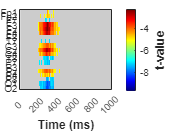

mT = Results.CON_ConditionB.Obs;
mT2 = mT;

mT(not(Results.CON_ConditionB.Mask))=0;

intercept = squeeze(betas(:,:,1));
beta = squeeze(betas(:,:,2));
cmap =colormap('jet');

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Antonino\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.3 to the path
EEGLAB: adding "EEG-Beats" v1.1.1 (see >> help eegplugin_eegbeats)
EEGLAB: adding "FastICA" v25 to the pathEEGLAB: adding "Fieldtrip-lite" v20231015 to the path - new version 20240111 available
EEGLAB: adding "Fileio" v20231015 to the path - new version 20240111 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel) - new version 1.5 available
EEGLAB: adding "TBT" v2.6.2 (see >> help eegplugin_TBT)
EEGLAB: adding "TESA" v1.1.1 (see >> help eegplugin_tesa)
EEGLAB: adding "bva-io" v1.72 (see >> help eegplugin_bva_io) - new version 1.73 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.3 (see >> help eegplugin_dipfit) - new version 5.4 available
EEGLAB: adding "firfilt" v2.7.1 

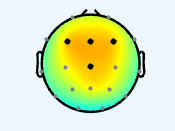

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [300×300 double]
           YData: [300×300 double]
           ZData: [300×300 double]
           CData: [300×300 double]

  Show all properties


% Raster plot
mT=mT(:,sEEG_times>=0);

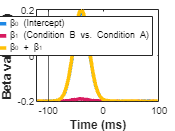

tick_labels = struct2table(chanlocs).labels;
figure,
imagesc(mT)
xlim([0 101])
set(gca,'ytick',1:19,'FontSize',8,'FontName','Arial');
set(gca,'TickLength',[0 0]);
set(gca,'XTick',linspace(1,101,6),'XTickLabel',0:200:1000,'FontSize',8,'FontName','Arial');
cmap2=cmap; cmap2(129,:)=[.8 .8 .8];
set(gca,'clim',[-max(abs(mT(:))) max(abs(mT(:)))],'colormap',cmap2) 
yticklabels(tick_labels);
xlabel("Time (ms)","FontWeight","bold","FontSize",10, "FontName","Arial");
set(gca,'color','none')
hc=colorbar;
a = get(hc,'YTickLabel')
set(hc, 'colormap', cmap,'YTickLabel',a,'FontSize',8,'FontName','Arial');

ylabel(hc,'t-value','FontWeight','bold','FontSize',10,'FontName','Arial');

% TOPOPLOT
[~, chm] = ismember({'Fz' 'F3' 'F4' 'Cz'}, struct2table(chanlocs).labels);
figure,
eeglab nogui
topoplot(mean(mT2(:,38:44),2), chanlocs, 'style', 'map', 'gridscale', 300, ...
    'maplimits', [-20 20], 'emarker',{'.',[.5 .5 .5],[],1},'emarker2',{chm,'o','k',4,1},'colormap',cmap)

%TRACEPLOT
figure,
y1 = mean(intercept(chm,:),1);
y2 = mean(beta(chm,:),1);
y3 = mean(intercept(chm,:)+beta(chm,:),1);
plot(sEEG_times,y1,"Color",[30 136 229]/255,"LineWidth",3);
hold on, plot(sEEG_times,y2,"Color",[216 27 96]/255,"LineWidth",3);
hold on, plot(sEEG_times,y3,"Color",[255 193 7]/255,"LineWidth",3);
yline(0), xline(0), xlim([-100 1000])
a = get(gca,"XTickLabel"); set(gca,"XTickLabel",a,"FontSize",8,"FontName","Arial");
a = get(gca,"YTickLabel"); set(gca,"YTickLabel",a,"FontSize",8,"FontName","Arial");
xlabel("Time (ms)","FontWeight","bold","FontSize",10, "FontName","Arial");
ylabel("Beta value (μV)","FontWeight","bold","FontSize",10, "FontName","Arial");
legend("β_0 (Intercept)", "β_1 (Condition B vs. Condition A)", "β_0 + β_1", Location="northeast");